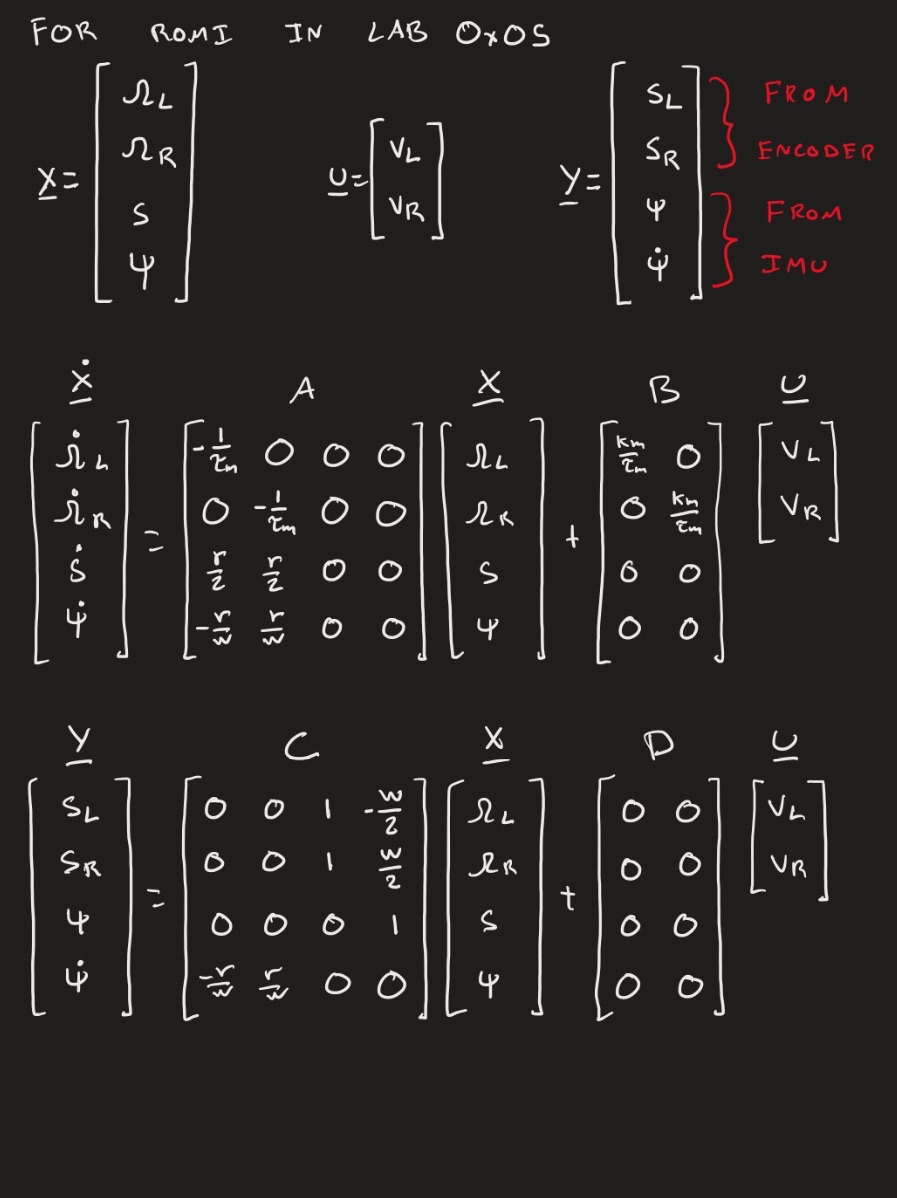


% Electromechanical properties
K      = 250*2*pi/60/4.5;   % Motor Gain [rad/(V*s)]
tau    = 0.1            ;   % Motor Time Constant [s]
r      = 35             ;   % Wheel Radius [mm]
w      = 141            ;   % Width between wheels [mm]

speed_multiplier = 10;
T_s = 0.05 ;% Time step in seconds

A = [-1/tau     0       0   0,
      0         -1/tau  0   0,
      r/2       r/2     0   0,
      -r/w      r/2     0   0];
B = [K/tau  0,
     0      K/tau,
     0      0,
     0      0];
C = [0      0       1   -w/2,
     0      0       1   w/2,
     0      0       0   1,
     -r/w   r/w     0   0];
D = zeros([4,2]);

% Create the state-space model object
sys_ss = ss(A, B, C, D);

% Get the poles of the system model
poles = pole(sys_ss);

desired_poles = poles.*speed_multiplier;

L = place(A', C', desired_poles)';

A_zero = A - L*C;
B_zero = [B-L*D, L];
new_sys = ss(A_zero, B_zero, C, 0);

disc = c2d(new_sys, T_s);

A_d = disc.A;
B_d = disc.B;

disp(A_d);

    0.4542    0.4465    0.2152    0.0815
    0.4465    0.4542    0.1958    0.1210
    0.1836    0.1641    0.2806   -0.3541
    0.0659    0.1054   -0.3541    0.8245



disp(B_d);

    1.6280    1.0478   -0.1070   -0.1082   -0.0000   -1.6803
    1.0478    1.6280   -0.0970   -0.0987   -0.0000    1.9724
    0.4308    0.3851    0.3572    0.3622    0.0000   -0.4556
    0.1547    0.2474    0.1758    0.1783    0.0000    1.4227



disp(disc.C);

         0         0    1.0000  -70.5000
         0         0    1.0000   70.5000
         0         0         0    1.0000
   -0.2482    0.2482         0         0

